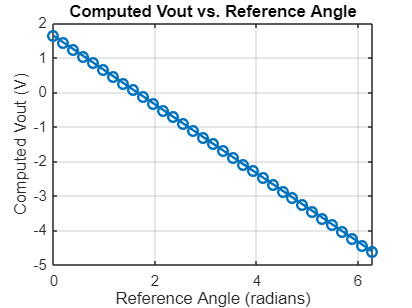

clear; clc;


phi = pi/32; 
delta_theta_actual = 1.5; 


reference_angles = 0:pi/16:2*pi; 
computed_delta_thetas = zeros(size(reference_angles)); 
V_n = cos(delta_theta_actual + (-1:1) * phi);
for idx = 1:length(reference_angles)
    ref_angle = reference_angles(idx);
   
    
    

    V_neg1 = V_n(1);
    V_0 = V_n(2);
    V_1 = V_n(3);
    
    DC = (V_neg1 + V_0 + V_1) / 3;
    
    ABk = - (V_1 - V_neg1) / phi;
    
    computed_delta_theta = (ref_angle) + (2 * (V_0) * phi) / (V_1 - V_neg1);
    
    computed_delta_thetas(idx) = -(ABk/2)*(computed_delta_theta-pi/2);
end

figure;
plot(reference_angles, computed_delta_thetas, '-o', 'LineWidth', 1.5);
xlabel('Reference Angle (radians)');
ylabel('Computed Vout (V)');
title('Computed Vout vs. Reference Angle');
grid on;